Script to try to visualise spherical convolutions. Firstly just building some signals, fODF etc. and then trying to implement the integral to perform the actual spherical conv. 

## Points to sample in the discretised integral

n_sample = 200;
dummy_scheme = gen_scheme(n_sample, 8);
theta = dummy_scheme.el;
phi = dummy_scheme.az;

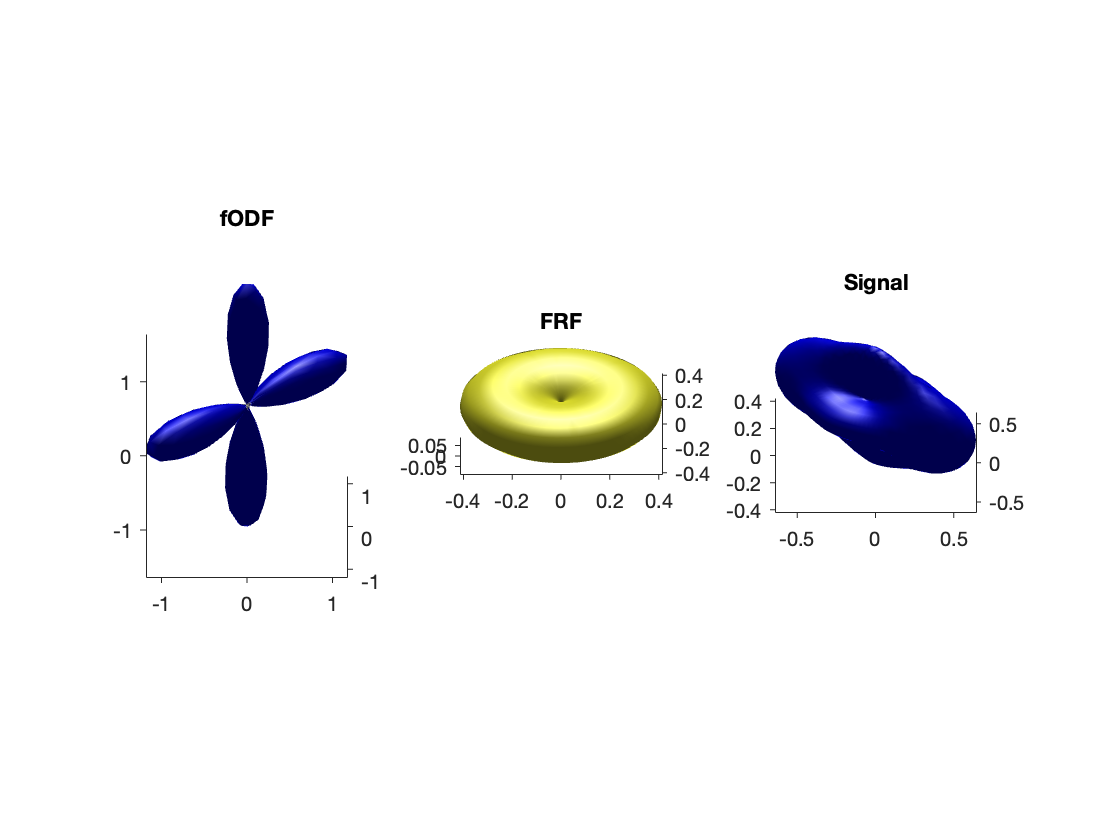

%% Build signal, FRF, fODF 
HR_scheme = gen_scheme (64, 8); %Scheme to simulate dMRI signals
HR_scheme_sr = gen_scheme(300, 8); %Use a scheme with more dirs for fODF estimate
S = eval_DT (0.8, 3, HR_scheme, 0, 0) + eval_DT (0.8, 3, HR_scheme, pi/2, pi/4);
S_SH = amp2SH (S, HR_scheme);
R = eval_DT (0.8, 3, HR_scheme);
R_SH = amp2SH (R, HR_scheme);
R_RH = SH2RH (R_SH);
[ F_SH_csd, num_it ] = csdeconv (R_RH, S, HR_scheme, HR_scheme_sr);
pscheme = gen_scheme(2000, 8);
figure(1); clf
subplot(1, 3, 1)
plot_SH (F_SH_csd, pscheme, [0,0,1,1]); view(0, 30); axis image; title('fODF')
subplot(1, 3, 2)
plot_RH(R_RH, pscheme);  view(0, 30); axis image; title('FRF')
subplot(1, 3, 3)
plot_SH(S_SH, pscheme, [0,0,1,1]); 
view(0,30); axis image; title('Signal')

%% Now let's try to implement the integral. We need to do a few things. 
% Firstly, let's set up an array to store the sconv signal 
S_sconv = nan(length(HR_scheme.el), 1);

%Setup scheme to compute amplitudes of rotated things 
fodf_amp = SH2amp(F_SH_csd, dummy_scheme);

% Movie to capture animation 
% M(length(theta)^2) = struct('cdata', [], 'colormap', []);
V = VideoWriter("./figs/sconv_vid.mp4", "MPEG-4");
open(V);

%Open a figure
h = figure(2);
h.Visible = 'off';
ax_dummy = subplot(2, 3, [2,3]); 
ax_integ = subplot(2, 3, [5,6]); 
plot(ax_integ, SH2amp(S_SH, HR_scheme), 'r');
xlim(ax_integ, [0, length(HR_scheme.el)])
ax_fodf = subplot(2, 3, [1,4]); 
%Loop over the directions 
for iDir = 1:length(HR_scheme.el)
    % the direction we're sampling
    dir = [cos(HR_scheme.az(iDir))*sin(HR_scheme.el(iDir)), sin(HR_scheme.az(iDir))*sin(HR_scheme.el(iDir)), cos(HR_scheme.el(iDir))];
    S_int = nan(length(theta), 1);
    % loop over dummy directions in integral
    for iDummy = 1:length(theta)
        cla(ax_fodf)
        dummy_dir = [cos(phi(iDummy))*sin(theta(iDummy)), sin(phi(iDummy))*sin(theta(iDummy)), cos(theta(iDummy))];
        %Rotation matrix in dummy dir
        rotmat = rot_mat_a_to_b([0,0,1], dummy_dir);
%         rotmat = [1, 0, 0; 0, cos(theta(iDummy)), -sin(theta(iDummy)); 0, sin(theta(iDummy)), cos(theta(iDummy))];
%         rotmat = [cos(phi(iDummy)), -sin(phi(iDummy)), 0; sin(phi(iDummy)), cos(phi(iDummy)), 0; 0, 0,1] * rotmat;
        %Rotate scheme to get rotated R 
        scheme_dirs = (rotmat * HR_scheme.vert')';
        rot_scheme = gen_scheme(scheme_dirs, 8);
        R_rot = amp2SH(R, rot_scheme);
        R_rot_amp = SH2amp(R_rot, HR_scheme);
        S_int(iDummy) = fodf_amp(iDummy) * R_rot_amp(iDir);
        
        %plot
        axes(ax_fodf)
        plot_SH(F_SH_csd, pscheme, [0,0,1,0.5]); hold on; view(0, 30); axis image off;
        plot3([0, dir(1)], [0,dir(2)], [0,dir(3)], 'm', 'LineWidth',3);
        plot3([0,dummy_dir(1)], [0, dummy_dir(2)], [0, dummy_dir(3)], 'g', 'LineWidth', 3)
        plot_SH(R_rot, pscheme, [1,1,0,0.5])
        
        plot(ax_dummy, S_int);
        ylim(ax_dummy, [-0.05,1])
        title(ax_dummy, 'Dummy integral')
        xlim(ax_dummy, [0, length(theta)])
        drawnow
        frm = getframe(h);
        V.writeVideo(frm);
    end
    %I'm not quite sure what the normalisation factor here should be
    S_sconv(iDir) = sum(S_int .* sin(theta))/(pi);
    cla(ax_integ);
    plot(ax_integ, SH2amp(S_SH, HR_scheme), 'r'); hold(ax_integ, 'on');
    plot(ax_integ, S_sconv, 'b')
    xlim(ax_integ, [0, length(HR_scheme.el)])
%     ylim(ax_integ, [0,1])
    title(ax_integ, 'Convolved signal')
end
close(V);